clc;clear all;close all;
k1=1;
m1=1;
c1=1;
c2=1;
m2=1;
k2=1;
A=[0 1 0 0;
-k1/m1 -c1/m1 k1/m1 c1/m1
0 0 0 1;
k1/m2 c1/m2 -(k1+k2)/m2 -c1/m2];
B=[0;0;0;k2/m2];
C=[1 0 0 0];
D=0;

nx = 4; %nx -> cantidad de estados X
ny = 1; %ny -> canidas de salidas  y, r, 3
nu = 1; %nu -> entradas u

%%Aumentar el sistema en lazo abierto
AOL=[A zeros(nx,ny);-C zeros(ny,ny)]

AOL =      0     1     0     0     0
    -1    -1     1     1     0
     0     0     0     1     0
     1     1    -2    -1     0
    -1     0     0     0     0


BOL=[B;zeros(ny,nu)]

BOL =      0
     0
     0
     1
     0


QOL=diag([100 1 1 1 1000])%  <----- el ultimo valor es la ganancia Ki

QOL =          100           0           0           0           0
           0           1           0           0           0
           0           0           1           0           0
           0           0           0           1           0
           0           0           0           0        1000


ROL=0.001;
KOL=lqr(AOL,BOL,QOL,ROL)

KOL = 1.0e+03 *

    0.7220    0.1997    0.0354    0.0374   -1.0000


K=KOL(:,1:nx)

K =   721.9506  199.6614   35.3581   37.3541


Ki=-KOL(:,(nx+1):end)

Ki = 1.0000e+03

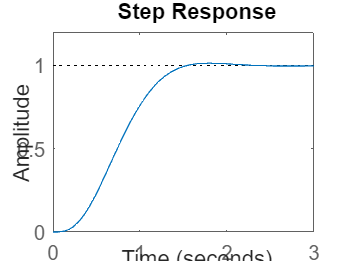


%Cerramos el sistema en lazo Cerardo
ACL=[A-B*K B*Ki;-C zeros(ny,ny)];
BCL=[zeros(nx,ny);eye(ny,ny)];
CCL=[C zeros(ny,ny)];
DCL=0;
GCL=ss(ACL,BCL,CCL,DCL);
step(GCL)